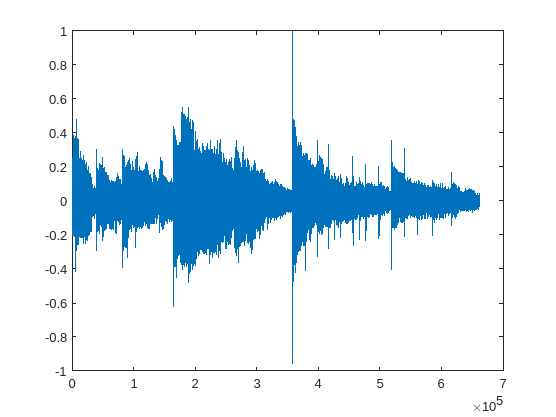

mu = 0.0020

b =     0.3942    0.8173    1.2500    1.2500    0.8173    0.3942


a =     1.0000    0.9156    1.4118    0.9298    0.5112    0.1546


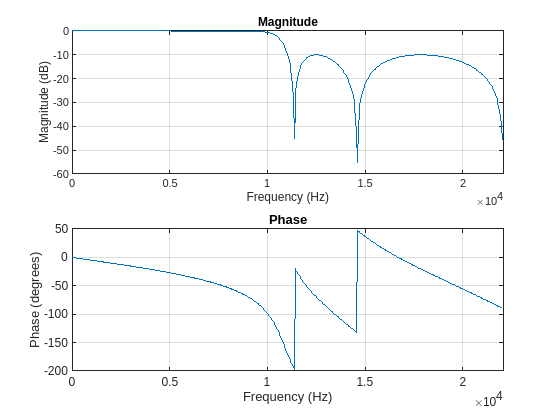

r_filt =     0.0016
    0.0010
   -0.0012
   -0.0032
   -0.0009
    0.0036
    0.0053
    0.0038
    0.0007
    0.0016


x =     0.0016
    0.0010
   -0.0012
   -0.0032
   -0.0009
    0.0036
    0.0053
    0.0038
    0.0007
    0.0016


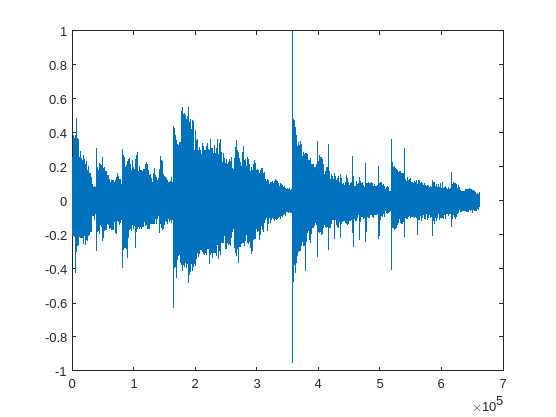

% read in a default audio file
[s, Fs] = audioread('guitartune.wav');

s = s'
plot(0:length(s)-1,s);
grid; axis([0 length(s)-1 -2 2]);
title('The information bearing signal');
% uncomment to play guitar sound
% sound(s, Fs)

nvar  = 1.0;                  % Noise variance
noise = (randn(length(s),1)*nvar)';   % White noise
plot(0:length(s)-1,noise);
title('Noise picked up by the secondary microphone');
grid; axis([0 1000 -4 4]);

% use some window filter... chebyshev? idk what numbers we want
lp = dsp.FIRFilter('Numerator',fir1(31,0.5));% Low pass FIR filter
[b, a] = fir1(31,0.5)
freqz(b, a, [], Fs)

% filter, put in transfer function and noise (with designated var)
filtered_noise = lp(noise)

% signal plus noise
signal_plus_noise = filtered_noise + s

% uncomment for sound of signal plus noise
% sound(signal_plus_noise, Fs)

D = s;
A = signal_plus_noise;

n = numel(D);

M = 25;
w = zeros(M,1);
wi = zeros(M,1);
R = [];
k = 1;
r = xcorr(A)
rr = [];

for i = 1:1:M
    rr(i) = r(n-1+1);
end

R = toeplitz(rr);
ei = max(eig(R));
u = 1/ei;
p = xcorr(D, A);

for i = 1:1:M
    P(i) = p(n-i+1);
end

for i = 1:10
    wi = w + u*(P'-R*w);
    w = wi;
end

% find the estimate
Est = zeros(n, 1)
for i = M:n
    j = A(i:-1:i-M+1);
    Est(i) = (wi)'*(j)';
end

% error signal
Err = Est' - D;

sound(signal_plus_noise, Fs)
